clear;clc;

netlist={
    uA741('e+','e-','out')
    'R1 e- out 29e3'
    'C1 out d1 159e-9'
    'R3 0 d1 1e3'
    'C2 d1 d2 159e-9'
    'R4 0 d2 1e3'
    'C3 d2 d3 159e-9'
    'R2 d3 e- 1e3'
    '.tran tstop=10 dtmax=1e-5 initTRAN=CI'
    '.probe out d3'
    };
sim=uacs(netlist)

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=1e-05, dt_min=1e-09, dt0=1e-12
18 Resistor(s), 0 Inductor(s), 7 Capacitor(s), 5 Diode(s), 3 Current Source(s), 9 Voltage Source(s) 24 electrical node(s)
Transient Simulation, t0=0, tmax=9.99975, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

200000 time steps computed in 176.266 seconds.


sim = struct with fields:
           X_t: [35×200000 double]
             t: [0 1.0000e-12 2.0000e-12 3.0000e-12 4.0000e-12 1.0040e-09 2.0040e-09 3.0040e-09 4.0040e-09 5.0040e-09 6.0040e-09 7.0040e-09 8.0040e-09 9.0040e-09 1.0004e-08 1.1004e-08 1.2004e-08 1.3004e-08 1.4004e-08 1.5004e-08 1.6004e-08 1.7004e-08 … ]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {2×1 cell}
      probe_id: [12 7]
         names: {1×35 cell}


R=1e3; R1=29e3;
C=1e-9;

f = 1/(2*pi*R*C*sqrt(6))

f = 6.4975e+04

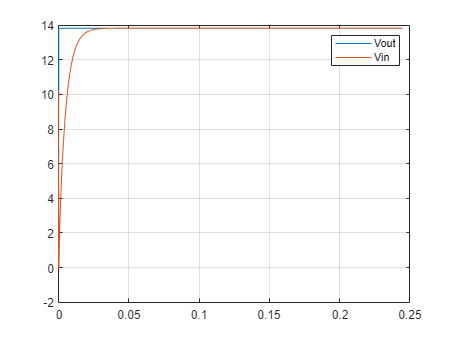


plot(sim.t,sim.X_t(sim.probe_id(1:2),:))
grid
legend('Vout','Vin')